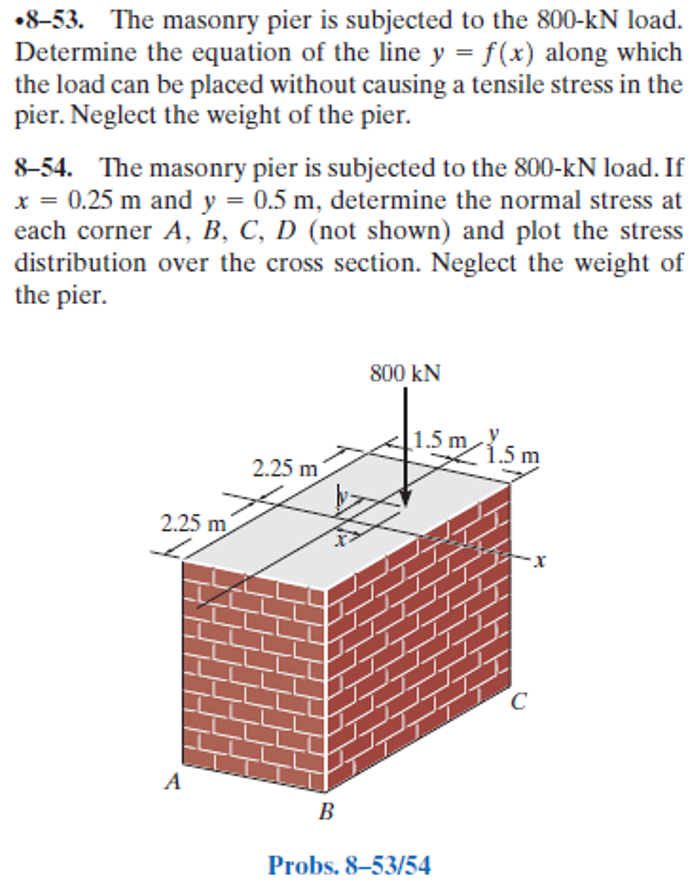

# given

u = symunit;
P = 800*u.kN;
B = 3*u.m;
H = 4.5*u.m;

# bending stress data

x = sym('x');
y = sym('y');
My(x) = P*x;
Mx(y) = P*y;
Iy = H*B^3/12;
Ix = B*H^3/12;

# equation of the neutral axis

[sigma(x, y) alpha(x, y)] = beam.unsymmetric(formula(My), formula(Mx), Iy, Ix, y, x); %#ok
x_zero = solve(sigma == 0, x);
alpha_zero = rewrite(alpha(x_zero, y), u.rad)/u.rad;
yfun(x) = alpha_zero(1)*x;